Inicializa os parâmetros

cd('../')
main
cd('MVO')

# Introdução

O objetivo da área de Mecânica de Voo é determinar o comportamento dinâmico da aeronave e realizar sua caracterização para o correto projeto dos controladores de voo. Modelos ruins resultam em controladores ruins.

# Capítulo 1. Modelagem e Simulação 6DOF

Equações

$\dot{u} = rv - qw + \frac{F_X}{m} - g \sin(\theta)  \\
\dot{v} = pw - ru + \frac{F_Y}{m} + g \cos(\theta)\sin(\phi)  \\
\dot{w} = qu - pv + \frac{F_Z}{m} + g \cos(\theta)\cos(\phi)  \\
\dot{p} = \frac{I_{xz}\dot{r}-(I_{zz}-I_{yy})qr + I_{xz}pq + l}{I_{xx}} \\
\dot{q} = \frac{-(I_{xx}-I_{zz})rp - I_{xz}(p^ 2 - r^2) + M}{I_{yy} \\
\dot{r} = \frac{I_{xz}\dot{p} - (I_{yy}-I_{xx})pq - I_{xz}qr + n}{I_{zz}} \\
\dot{\phi} = p + q \sin(\phi) tan(\theta) + r\cos(\phi)tan(\theta) \\
\dot{\theta} = q \cos(\phi) - r \sin(\phi) \\
\dot{\psi} = \frac{q\sin(\phi)+r\cos(\phi)}{\cos(\theta)} \\
\dot{x} = u\cos(\theta)\cos(\psi) + v(-\sin(\phi)\sin(\theta)\cos(\psi) + \cos(\phi)\sin(\psi)) + w(\cos(\phi)\sin(\theta)\cos(\psi) + \sin(\phi)\sin(\psi)) \\
\dot{y} = u\cos(\theta)\sin(\psi) + v(\sin(\phi)\sin(\theta)\sin(\psi) + \cos(\phi)\cos(\psi)) + w(-\cos(\phi)\sin(\theta)\sin(\psi) + \sin(\phi)\cos(\psi)) \\
\dot{z} = -u\sin(\theta) + v\sin(\phi)\cos(\theta) + w\cos(\phi)\cos(\theta)$  (1)

Simulink:

-  Bus --> Mux/Demux 

- Aerospace Toolbox 

- Importância das saídas

- Divisão por zero

# Capítulo 2. Trimagem

Trim = false;
Lin = true; 
model = 'TelemasterTrimLin';
load_system(model)

A Trimagem é um problema de equações algébricas não lineares que podem ter uma única solução quando o número de equações e incógnitas é o mesmo.

O modelo proposto possui dez estados de interesse (x e y não influenciam): 

- Velocidades Lineares | u, v, w

- Velodiades Angulares | p, q, r

- Atitude da Aeronave   | phi, theta, psi,

- Altitude                       | H

As entradas da aeronave foram definidas como: 

- aileron

- throttle

- elevator

- rudder

Ao total, 14 variáveis.

Cada etapa de voo da aeronave precisa ser trimada, para o projeto de controle adequ ado. Para o Telemaster, as fases são:

- Cruzeiro (Voo reto e nivelado) 

- Subida Nivelada (Variação na taxa de subida)

-  Pull-Up (Variação na taxa de arfagem) 

- Curva Coordenada (Variação na taxa de rolamento)

Todas as etapas acompanham um conjunto de restrições e de condições iniciais. As restrições são as equações que precisam ser definidas para o cálculo de equilíbrio.

Como o ângulo de ataque mínimo e máximo são, respectivamente, -10 e 15 graus, e $\alpha =\tan^{-1} \left(\frac{w}{u}\right)$, aproximando $u=V$, isso limita $w$ a: 


$$w=\tan \left(\alpha \;\right)*V$$


## Voo Reto e Nivelado

O Voo Reto e Nivelado caracteriza-se pelo voo, em caso de ausência de vento com as asas niveladas e com ângulo de trajetória nulo $\gamma =\theta -\alpha =0$.

As condições iniciais são:

- Velocidade Inercial, componente x - Ve

- Altitude Heq

As restrições para cálculo de equilíbrio são:

- Aceleração linear nula                 (u_dot,         v_dot,          w_dot   = 0)

- Aceleração angular nula              (p_dot,         q_dot,          r_dot    = 0)

- Taxa de variação angular nula     (phi_dot,      theta_dot,   psi_dot = 0)

- Velocidade inercial definida         (x_dot = Ve, y_dot e z_dot          = 0)

- Altitude                                         (z  = -Heq)

- Fator de carga lateral nulo           (nCb_y = 0 )

Ve  = 1:1:20;
Heq = 20;
motor.Flying = 0;
if Trim
    tic
    SteadyState = trim_SteadyState(Ve,Heq,model)
    toc
end

## Subida ou Descida

A existência de uma taxa de velocidade vertical determina a etapa de subida ou descida. A Altitude neste caso é apenas definida para determinar a pressão dinâmica no início da manobra.

As condições iniciais são:

- Velocidade Inercial, componente x - Ve

- Taxa de Subida Hdot

As restrições para cálculo de equilíbrio são:

- Aceleração linear nula                 (u_dot,         v_dot,          w_dot   = 0)

- Aceleração angular nula              (p_dot,         q_dot,          r_dot    = 0)

- Taxa de variação angular nula     (phi_dot,      theta_dot,   psi_dot = 0)

- Velocidade inercial definida         (x_dot = Ve, y_dot = 0 e z_dot  = -Hdot)

- Fator de carga lateral nulo           (nCb_y = 0 )

## Pull-Up

Uma manobra de pull-up tem como caracterísitca a existência de uma variação na taxa de arfagem. É com ela que se pode aproximar um "looping coordenado" com as ressalvas de que a mudança de altitude impacta nas forças aerodinâmicas. A Altitude neste caso é apenas definida para determinar a pressão dinâmica no início da manobra.

As condições iniciais são:

- Velocidade Inercial, componente x - Ve

- Taxa de Arfagem Thetadot

As restrições para cálculo de equilíbrio são:

- Aceleração linear nula                 (u_dot,              v_dot,                             w_dot   = 0)

- Aceleração angular nula              (p_dot,              q_dot,                             r_dot    = 0)

- Taxa de variação angular nula     (phi_dot = 0,     theta_dot = Thetadot,   psi_dot = 0)

- Velocidade inercial definida         (x_dot = Ve,      y_dot = 0  )

- Fator de carga lateral nulo           (nCb_y = 0 )

## Conclusão

if Trim
    save('Results/SteadyState.mat','SteadyState','-v7.3')
else
    load('Results\SteadyState.mat');
end


É sempre de bom tom conferir os resultados obtidos em um processo em lotes. Para verificar a correta convergência das variáveis, elas podem ser plotadas e com conhecimento do comportamento de uma aeronave, pode-se fazer o check de sanidade dos valores. As análises serão:

- Estado final - Estado inicial < 1e-3 --> Após simulação de 10 segundos, verificar o comportamento dos estados

- Throttle vs Airspeed

- Profundor vs Airspeed

cont1 = 1;
if Trim
    tic
    for cont = 1:length(SteadyState)
        if SteadyState(cont).trim
            u(:,2) = SteadyState(cont).op.Inputs(2, 1).u;
            u(:,3) = SteadyState(cont).op.Inputs(3, 1).u;
            set_param(model,'LoadInitialState','on','InitialState','getstatestruct(SteadyState(cont).op)')
            res_trim(cont1) = sim(model);
            plot_data(cont1,:) = [SteadyState(cont).V SteadyState(cont).op.Inputs(2, 1).u(1) SteadyState(cont).op.Inputs(3, 1).u(1) SteadyState(cont).alpha...
                                  SteadyState(cont).opreport.Outputs(31, 1).y(1) SteadyState(cont).opreport.Outputs(31, 1).y(2)];
            state_u      = (res_trim(cont1).yout.signals(15).values(end) - res_trim(cont1).yout.signals(15).values(1)) < 1e-1;
            state_v      = (res_trim(cont1).yout.signals(16).values(end) - res_trim(cont1).yout.signals(16).values(1)) < 1e-1;
            state_w      = (res_trim(cont1).yout.signals(17).values(end) - res_trim(cont1).yout.signals(17).values(1)) < 1e-1;
            state_p      = (res_trim(cont1).yout.signals(18).values(end) - res_trim(cont1).yout.signals(18).values(1)) < 1e-1;
            state_q      = (res_trim(cont1).yout.signals(19).values(end) - res_trim(cont1).yout.signals(19).values(1)) < 1e-1;
            state_r      = (res_trim(cont1).yout.signals(20).values(end) - res_trim(cont1).yout.signals(20).values(1)) < 1e-1;
            state_phi    = (res_trim(cont1).yout.signals(21).values(end) - res_trim(cont1).yout.signals(21).values(1)) < 1e-1;
            state_theta  = (res_trim(cont1).yout.signals(22).values(end) - res_trim(cont1).yout.signals(22).values(1)) < 1e-1;
            state_psi    = (res_trim(cont1).yout.signals(23).values(end) - res_trim(cont1).yout.signals(23).values(1)) < 1e-1;
            state_z      = (res_trim(cont1).yout.signals(24).values(end) - res_trim(cont1).yout.signals(24).values(1)) < 1e-1;
            if (state_u && state_v && state_w && state_p && state_q && state_r && state_phi && state_theta && state_psi && state_z)
                SteadyState(cont).trim = 1;
            else
                SteadyState(cont).trim = 2;
            end
            cont1 = cont1+1;
        end
    end
    save('Results\plot_data.mat','plot_data','-v7.3')
    save('Results\res_trim.mat','res_trim','-v7.3')
    toc
else
    load('Results\plot_data.mat')
    load('Results\res_trim.mat')
end

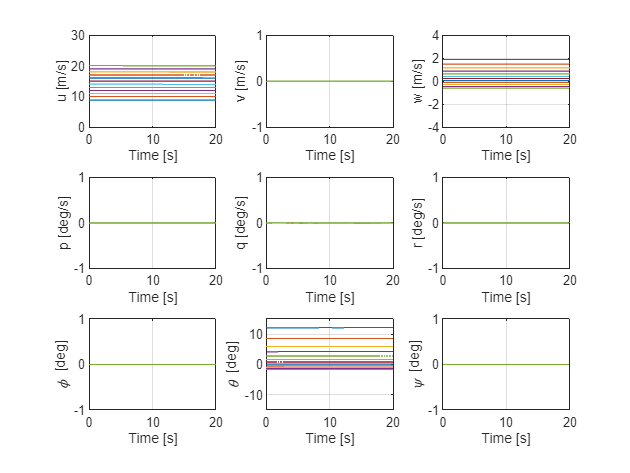

figure(1)
for cont = 1:length(res_trim)
    subplot(3,3,1)
    plot(res_trim(cont).tout,res_trim(cont).yout.signals(15).values)
    xlabel('Time [s]')
    ylabel('u [m/s]')
    hold on
    grid on
    subplot(3,3,2)
    plot(res_trim(cont).tout,res_trim(cont).yout.signals(16).values)
    xlabel('Time [s]')
    ylabel('v [m/s]')
    hold on
    grid on
    subplot(3,3,3)
    plot(res_trim(cont).tout,res_trim(cont).yout.signals(17).values)
    xlabel('Time [s]')
    ylabel('w [m/s]')
    hold on
    grid on
    subplot(3,3,4)
    plot(res_trim(cont).tout,res_trim(cont).yout.signals(18).values)
    xlabel('Time [s]')
    ylabel('p [deg/s]')
    hold on
    grid on
    subplot(3,3,5)
    plot(res_trim(cont).tout,res_trim(cont).yout.signals(19).values)
    xlabel('Time [s]')
    ylabel('q [deg/s]')
    hold on
    grid on
    subplot(3,3,6)
    plot(res_trim(cont).tout,res_trim(cont).yout.signals(20).values)
    xlabel('Time [s]')
    ylabel('r [deg/s]')
    hold on
    grid on
    subplot(3,3,7)
    plot(res_trim(cont).tout,res_trim(cont).yout.signals(21).values)
    xlabel('Time [s]')
    ylabel('\phi [deg]')
    hold on
    grid on
    subplot(3,3,8)
    plot(res_trim(cont).tout,res_trim(cont).yout.signals(22).values)
    xlabel('Time [s]')
    ylabel('\theta [deg]')
    hold on
    grid on
    subplot(3,3,9)
    plot(res_trim(cont).tout,res_trim(cont).yout.signals(23).values)
    xlabel('Time [s]')
    ylabel('\psi [deg]')
    hold on
    grid on
end
subplot(3,3,1); ylim([0 30]);
subplot(3,3,2); ylim([-1 1]);
subplot(3,3,3); ylim([-4 4]);
subplot(3,3,4); ylim([-1 1]);
subplot(3,3,5); ylim([-1 1]);
subplot(3,3,6); ylim([-1 1]);
subplot(3,3,7); ylim([-1 1]);
subplot(3,3,8); ylim([-15 15]);
subplot(3,3,9); ylim([-1 1]);
hold off

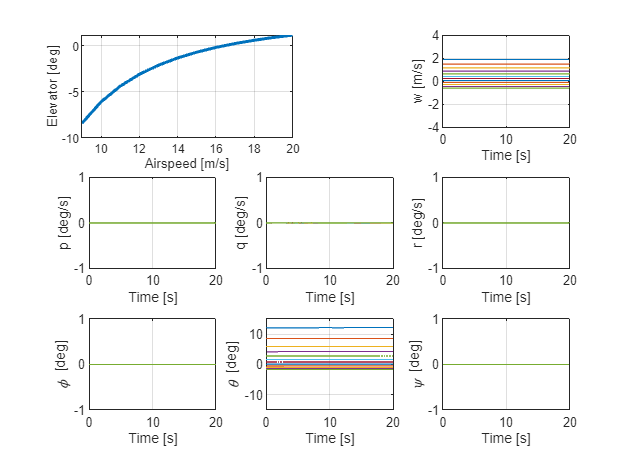

figure(2)
subplot(3,2,1)
plot(plot_data(:,1),plot_data(:,3),LineWidth=2)
xlabel('Airspeed [m/s]')
ylabel('Elevator [deg]')
grid on
hold off

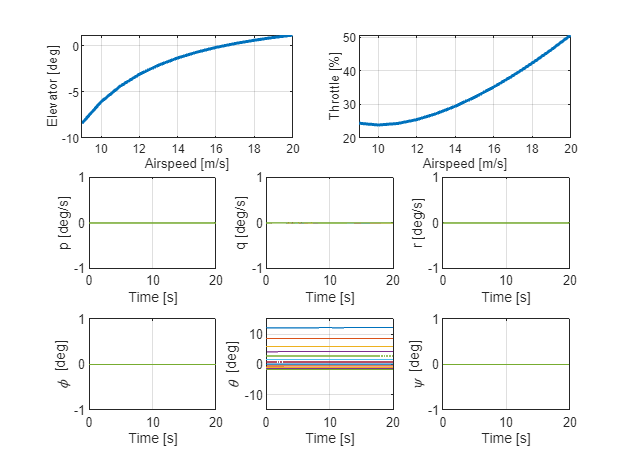

subplot(3,2,2)
plot(plot_data(:,1),plot_data(:,2)*100,LineWidth=2)
hold on
xlabel('Airspeed [m/s]')
ylabel('Throttle [%]')
grid on
hold off

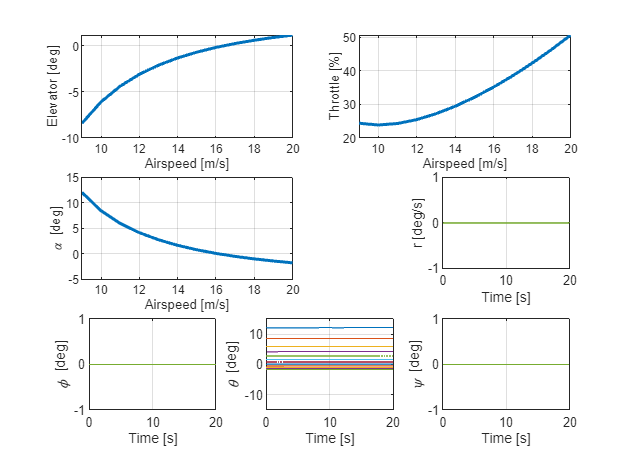

subplot(3,2,3)
plot(plot_data(:,1),plot_data(:,4),LineWidth=2)
hold on
xlabel('Airspeed [m/s]')
ylabel('\alpha [deg]')
grid on
hold off

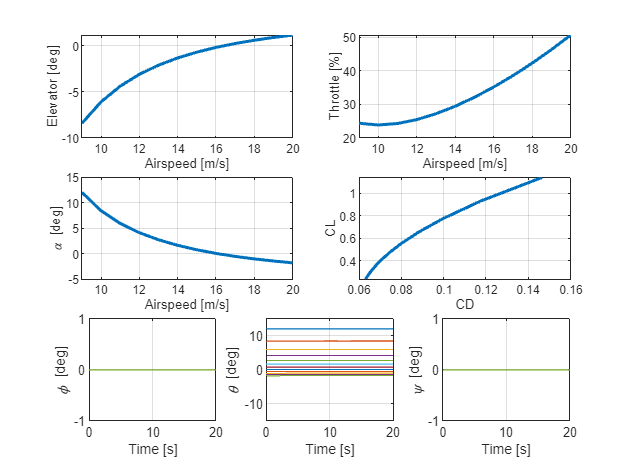

subplot(3,2,4)
plot(plot_data(:,6),plot_data(:,5),LineWidth=2)
hold on
xlabel('CD')
ylabel('CL')
grid on
hold off

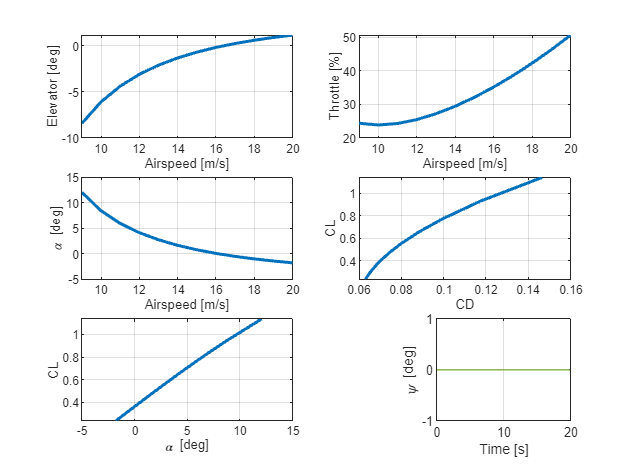

subplot(3,2,5)
plot(plot_data(:,4),plot_data(:,5),LineWidth=2)
hold on
xlabel('\alpha [deg]')
ylabel('CL')
grid on
hold off

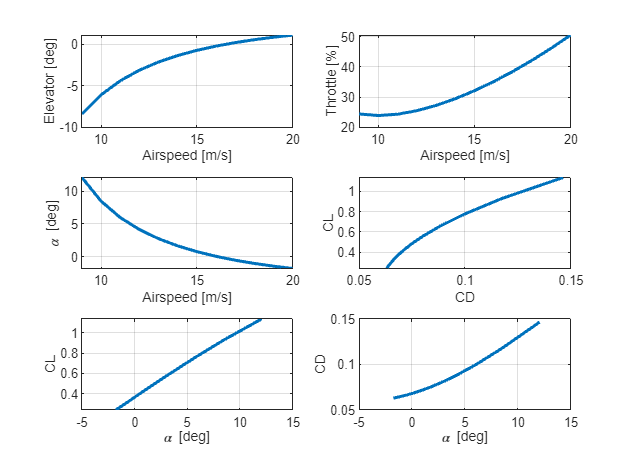

subplot(3,2,6)
plot(plot_data(:,4),plot_data(:,6),LineWidth=2)
hold on
xlabel('\alpha [deg]')
ylabel('CD')
grid on
hold off

# Capítulo 3 - Linearização

A Linearização permite analisar em detalhe modos dinâmicos da aeronave e também utilizar ferramentas conceituadas para desenvolvimento de controladores.

Para cada condição trimada, é possível encontrar um ponto de linearização de interesse.

## Longitudinal

Os estados, sídas e controles de interesse do modo longitudinal, que constituem o movimento de curto período e fugóide são:


$$\begin{array}{l}
X=u,w,q,\theta \;,z\\
Y=V,\alpha ,q,\theta ,H,n_z 
\end{array}$$


if Trim
else
    load('Results\SteadyState.mat');
end

% Steady State
for cont = 1:length(SteadyState)
    SteadyState(cont).G = [];
    SteadyState(cont).G_lon = [];
    SteadyState(cont).G_lat = [];
    SteadyState(cont).LonStable = [];
    if SteadyState(cont).trim
        G = linearize(model,SteadyState(cont).op,'StateOrder',{'u','v','w','p','q','r','phi','theta','psi','Ze'});
        G.OutputName = {'u_dot','v_dot','w_dot','p_dot','q_dot','r_dot','phi_dot','theta_dot','psi_dot','x_dot','y_dot','z_dot',...
                        'nCb_y','H','u','v','w','p','q','r','phi','theta','psi','z','alpha','beta','V','ax','ay','az',...
                        'CL','CD','CM','L','D','M','CY','Cl','Cn','Y','l','n','CL0','CD0','CM0','CLa','CLde','CLq','CMa',...
                        'CMde','CMq','Cldr','Clda','CYdr','CYda','CYr','CYb','CYp','Clb','Clp','Clr','Cndr','Cnda','Cnb','Cnp','Cnr',...
                        'HMe','HMr','HMa','FuelFlow','RPM','FuelMass','Fp_x'};
        xLon = {'u','w','q','theta','Ze'};
        xLat = {'v','p','r','phi'};
        [~,xElim] = setdiff(G.StateName,xLon);
        G_lon = modred(G,xElim,'truncate');
        G_lon = G_lon([27,25,19,22,14,30],[2,3]);
        [~,xElim] = setdiff(G.StateName,xLat);
        G_lat = modred(G,xElim,'truncate');
        G_lat = G_lat([16,18,20,21,23,26,29],[1,4]);
        SteadyState(cont).G = G;
        SteadyState(cont).G_lon = G_lon;
        SteadyState(cont).G_lat = G_lat;
        if (isstable(minreal(G_lon)))
            SteadyState(cont).LonStable = 1;
        else
            SteadyState(cont).LonStable = 0;
        end
    end
end

if Lin
    save('Results/SteadyState.mat','SteadyState','-v7.3')
else
end
